# Exploratory Data Analysis on Severe Weather Event Costs

This project uses real-world storm event data from NOAA to demonstrate fundamental data science techniques in MATLAB. We'll import, clean, and analyze data to understand which severe weather events cause the most economic damage in the U.S.

## Data Import Section

% Set file path
filename = 'StormEvents_locations-ftp_v1.0_d2023_c20250401.csv';

opts = detectImportOptions(filename);
opts.SelectedVariableNames = {'YEARMONTH', 'EPISODE_ID', 'EVENT_ID', 'LOCATION', ...
                              'LATITUDE', 'LONGITUDE', 'LAT2', 'LON2'};

stormLocations = readtable(filename, opts);

% Preview the dataset
head(stormLocations)

    YEARMONTH    EPISODE_ID    EVENT_ID          LOCATION         LATITUDE    LONGITUDE       LAT2          LON2   
    _________    __________    _________    __________________    ________    _________    __________    __________

    2.023e+05    1.7674e+05    1.074e+06    {'ABERNATHY ARPT'}      35.18       -87.05     3.5108e+06      8.73e+05
    2.023e+05    1.7674e+05    1.074e+06    {'PROSPECT'      }      35.01       -87.01          35600         87600
    2.023e+05    1.7674e+05    1.074e+06    {'NASHVILLE'     }      36.17       -86.81     3.6102e+06    8.6486e+06
    2.023e+05    1.7674e+05    1.074e+06    {'GOODLETTSVILLE'}     36.322      -86.712     3.6193e+06    8.6427e+06
    2.023e+05    1.7674e+05    

summary(stormLocations)


stormLocations: 43572x8 table

Variables:

    YEARMONTH: double
    EPISODE_ID: double
    EVENT_ID: double
    LOCATION: cell array of character vectors
    LATITUDE: double
    LONGITUDE: double
    LAT2: double
    LON2: double

Statistics for applicable variables:

                  NumMissing         Min            Median           Max              Mean              Std      

    YEARMONTH         0              202301          202306          202312        2.0231e+05            2.7506  
    EPISODE_ID        0              175219          181491          187950        1.8156e+05        3.1968e+03  
    EVENT_ID          0             1062433         1107092         1154656        1.1092e+06        2.3215e+04  
    LOCATION          0                                                                                          
    LATITUDE          0            -14.3429         37.3509         66.6546           37.1230            5.6287  
    LONGITUDE         0           -170.8744

## Basic Scatter Plot of Storm Locations

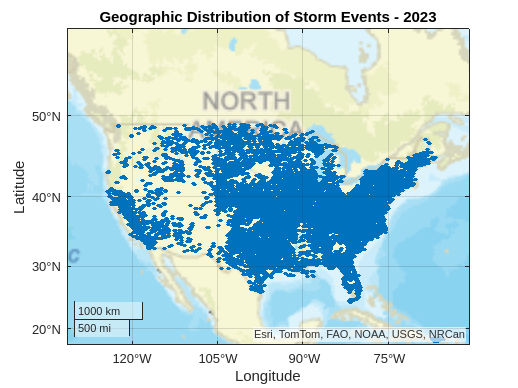

% Filter out rows with missing coordinates
validCoords = ~isnan(stormLocations.LATITUDE) & ~isnan(stormLocations.LONGITUDE);
stormCoords = stormLocations(validCoords, :);

% Create scatter plot of storm locations
figure
geoscatter(stormCoords.LATITUDE, stormCoords.LONGITUDE, 10, 'filled')
title('Geographic Distribution of Storm Events - 2023')
geobasemap streets

geolimits([17.4 58.8],[-131.5 -60.8])

## Frequency Analysis Section

% Remove invalid coordinates
validLat = abs(paths.LATITUDE) <= 90 & abs(paths.LAT2) <= 90;
validLon = abs(paths.LONGITUDE) <= 180 & abs(paths.LON2) <= 180;

paths = paths(validLat & validLon, :);

% Remove missing or blank locations
stormCoords.LOCATION = string(stormCoords.LOCATION);
validLocs = stormCoords(stormCoords.LOCATION ~= "", :);

% Count how often each location appears
[locCounts, locNames] = groupcounts(validLocs.LOCATION);

% Combine into a table
locationCounts = table(locNames, locCounts, 'VariableNames', {'Location', 'EventCount'});

% Sort by count descending
locationCounts = sortrows(locationCounts, "EventCount", "descend");

% Show top 10 locations
topLocations = locationCounts(1:10, :)

topLocations = 10x2 table
         Location         EventCount
    __________________    __________

    "SAN JUAN"               183    
    "PLAYALINDA BEACH"        75    
    "SPRINGVILLE"             63    
    "VIEUX CARRE"             58    
    "PONCE"                   56    
    "MAYPORT NAS"             51    
    "NAGUABO"                 49    
    "NORFOLK"                 48    
    "FAIRVIEW"                46    
    "DUNLAP"                  45    


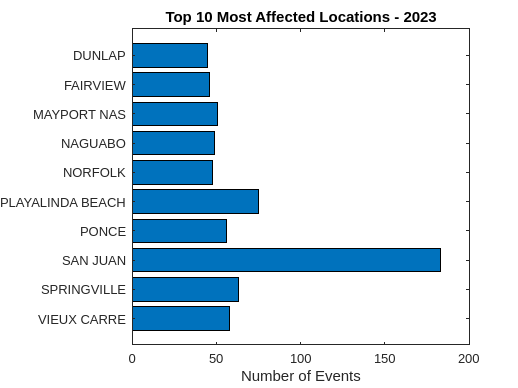


% Plot top 10
figure
barh(categorical(topLocations.Location), topLocations.EventCount)
xlabel('Number of Events')
title('Top 10 Most Affected Locations - 2023')
set(gca, 'YDir','reverse')

## Summary

This analysis shows the geographic footprint of storm activity in the U.S. during 2023.